clc
clear
close all
set(0,'defaultAxesFontSize', 12)
set(0, 'DefaultLineLineWidth', 2);

## Load data ex 1: restaturant profit estimation

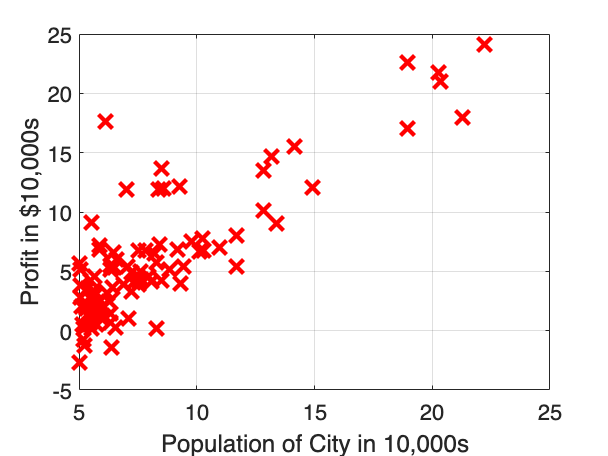

data = load('Data/ex1data1.txt');
X = data(:, 1); % regressors matrix
y = data(:, 2); % output
N = length(y); % number of training samples \ observations

figure; % open a new figure window
plot(X, y, 'rx', 'MarkerSize', 10); % Plot the data
ylabel('Profit in $10,000s'); % Set the yaxis label
xlabel('Population of City in 10,000s'); % Set the xaxis label
grid on

## Gradient descent

fprintf('Running Gradient Descent ...\n')

X = [ones(N, 1), data(:,1)]; % Add a column of ones to x
theta_hat = zeros(2, 1); % initialize fitting parameters

% Some gradient descent settings
iterations = 1500; % number of gradient descent iterations
alpha = 0.01; % learning rate

% run gradient descent
theta_hat = gradientDescent(X, y, theta_hat, alpha, iterations);

% print theta to screen
fprintf('Theta found by gradient descent: ');
fprintf('%f %f \n', theta_hat(1), theta_hat(2));

% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta_hat, 'b-o')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure

% Predict values for population sizes of 35,000
profit_hat = [1, 3.5] *theta_hat;
fprintf('For population = 35,000, we predict a profit of %f\n',...
    profit_hat*10000);

## Visualizing J(theta_0, theta_1)

fprintf('Visualizing J(theta_0, theta_1) ...\n')

% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
        t = [theta0_vals(i); theta1_vals(j)];
        J_vals(i,j) = computeCost(X, y, t);
    end
end


% Because of the way meshgrids work in the surf command, we need to
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';
% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta_hat(1), theta_hat(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);

## Load Data ex 2: house prices estimation

clc
clear
close all

data = load('Data\ex1data2.txt');
X = data(:, 1:2); % regressors matrix
y = data(:, 3); % output
N = length(y); % number of training samples \ observations

% Print out some data points
fprintf('First 10 examples from the dataset: \n');
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

## Least squares - normal equations

% ====================== YOUR CODE HERE ===================================
% Instructions: Compute the estimate for linear regression using normal equations

% You need to estimate the following variables correctly
theta_hat = 0; % insert here the code, instead of " = 0";

% =========================================================================


% Display normal equation's result
fprintf('Theta computed from the normal equations: \n');
fprintf(' %f \n', theta_hat);
fprintf('\n');


% Estimate the price of a 1650 sq-ft, 3 br house
price_hat = [1 1650 3]*theta_hat;

fprintf(['Predicted price of a 1650 sq-ft, 3 br house ' ...
    '(using normal equations):\n $%f\n'], price_hat);
fprintf('\n');
fprintf('\n');

## Gradient Descent

% Scale features and set them to zero mean
fprintf('Normalizing Features ...\n');

[Z mu sigma] = featureNormalize(X); % normalize data

% Add intercept term to normalized data matrix Z
Xaug = [ones(N, 1) Z];

fprintf('Running gradient descent ...\n');

% Choose some alpha value
alpha = 0.01;
num_iters = 500;

% Init Theta and Run Gradient Descent
theta_hat = zeros(3, 1);
[theta_hat, J_history] = gradientDescentMulti(Xaug, y, theta_hat, alpha, num_iters);

% Plot the convergence graph
figure;
plot(1:numel(J_history), J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J'); grid on;

% Display gradient descent's result
fprintf('Theta computed from gradient descent: \n');
fprintf(' %f \n', theta_hat);
fprintf('\n');

% Estimate the price of a 1650 sq-ft, 3 br house
% Recall that the first column of X is all-ones. Thus, it does
% not need to be normalized.

z = ([1650 3] - mu)./sigma; % now you should work with normalized data
z = [1 z]; % add dummy regressor for intercept term to normalized data
price_hat = z*theta_hat ;  % estimated price

% ============================================================

fprintf(['Predicted price of a 1650 sq-ft, 3 br house ' ...
    '(using gradient descent):\n $%f\n'], price_hat);